**POSIZIONI A MANO E VELOCITA' ANGOLARE CON MOVING FRAMES**

Per prima cosa definiamo quante sono le coordinate generalizzate del robot:

n=3 

n = 3

**Ricorda che la formula che utilizziamo è la seguente:**


$$T_i(q)=\frac{1}{2}m_i \left(V_{cm_i}^w\right)^T V^w_{cm_i} +\frac{1}{2}\left(\omega^i_i\right)^TI_i \ \omega_i^i$$


dove il $V_{cm_i}^w$ indica la velocità del centro di massa del frame i rispetto il **world frame **e dove:


$$\omega^i_i=\left(R_i^{ i-1}(q_i) \right)^T \left( \omega_{i-1}^{i-1} +\omega_i\right)$$


dove $\omega_i$ è la velocità angolare data dal joint i (che è un vettore attaccato al frame i-1) la potremmo scirvere come $\omega^{i-1}_{joint _i}$=$\omega_i z^{i-1}_{i-1}$ ed è praticamente la stessa cosa del mooving frame, infatti il vettore $z_{i-1}^{i-1}$ è sempre ugale a $(0 \ 0 \ 1 )^T$. quindi posso scrivere $\omega_i=\omega_i^{i-1}$, ovvero contirbuito del joint i espresso nel frame i-1.

Poi dobbiamo definire tutte le variabili simboliche di nostro utilizzo:

q = sym('q', [n, 1]);
for i=1:n
    nomeVariabile = ['q' num2str(i)];
    assignin('base', nomeVariabile,q(i,1));
end

L = sym('l', [n, 1]);
for i=1:n
    nomeVariabile = ['l' num2str(i)];
    assignin('base', nomeVariabile,L(i,1));
end

%inertia matrix for each link
I = sym('Ic', [3, 3, n]);
for i=1:n
    I(1,1,i)=sym(['Ic' num2str(i) 'xx']);I(1,2,i)=sym(['Ic' num2str(i) 'xy']); I(1,3,i)=sym(['Ic' num2str(i) 'xz']);
    I(2,1,i)=sym(['Ic' num2str(i) 'yx']);I(2,2,i)=sym(['Ic' num2str(i) 'yy']); I(2,3,i)=sym(['Ic' num2str(i) 'yz']);
    I(3,1,i)=sym(['Ic' num2str(i) 'zx']);I(3,2,i)=sym(['Ic' num2str(i) 'zy']); I(3,3,i)=sym(['Ic' num2str(i) 'zz']);
end

m = sym('m', [n, 1]);
for i=1:n
    nomeVariabile = ['m' num2str(i)];
    assignin('base', nomeVariabile,m(i,1));
end

pcx = sym('pcx', [1,n]);
for i=1:n
    nomeVariabile = ['pcx' num2str(i)];
    assignin('base', nomeVariabile,pcx(1,i));
end
pcy = sym('pcy', [1,n]);
for i=1:n
    nomeVariabile = ['pcy' num2str(i)];
    assignin('base', nomeVariabile,pcy(1,i));
end
pcz = sym('pcz', [1,n]);
for i=1:n
    nomeVariabile = ['pcz' num2str(i)];
    assignin('base', nomeVariabile,pcz(1,i));
end

pcz=subs(pcz,pcz,zeros(1,n));  % da cancellare se si vogliono fare calcoli con pcz

uni=ones(1,n);
com=[pcx;pcy;pcz;uni]

$$com = \left(\begin{array}{ccc} {\mathrm{pcx}}_{1} & {\mathrm{pcx}}_{2} & {\mathrm{pcx}}_{3}\\ {\mathrm{pcy}}_{1} & {\mathrm{pcy}}_{2} & {\mathrm{pcy}}_{3}\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

Adesso dobbiamo notare che molto spesso ci sono delle condizioni che semplificano la posizione del centro di massa.

**When the center of mass is located on the kinematics axis of the links **we can introduce other variables in order to characterize well the position of the center of mass. 

D = sym('dc', [n, 1]);
for i=1:n
    nomeVariabile = ['dc' num2str(i)];
    assignin('base', nomeVariabile,D(i,1));
end

In questo caso la situazione  opposta rispetto a quella considerata normalmente, in generale le quantità dc vanno dal centro di massa del link i al frame i 

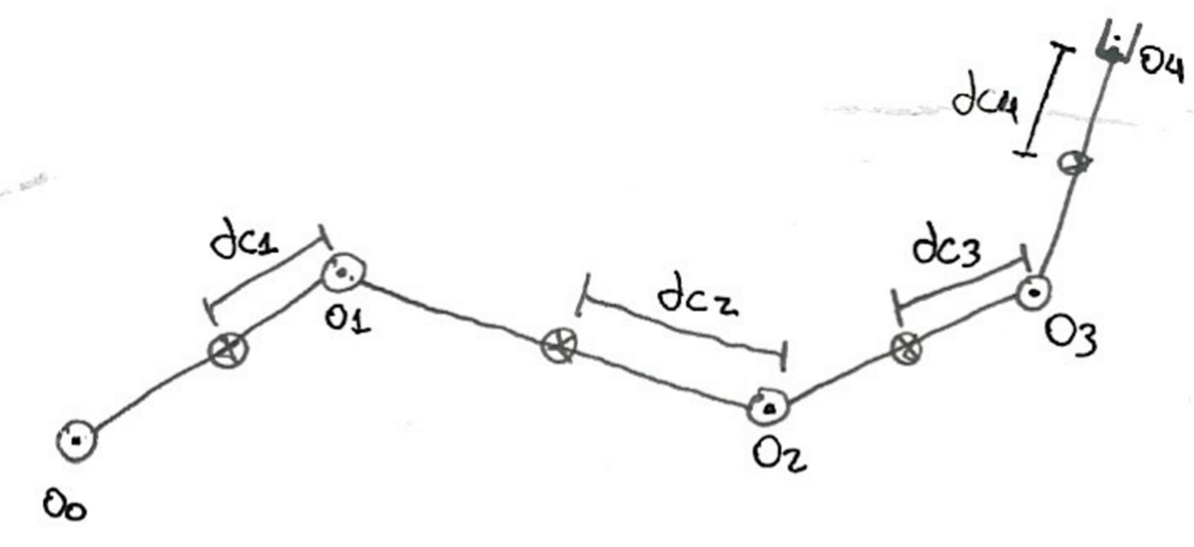

**Corretta assegnazione delle variabili simboliche rispetto il nostro esercizio ( a mano ) **

Purtroppo come assegnare i parametri dc alle variabili del vettore com **va fatto a mano,** perche ci sono troppe complicazioni nel farlo in matlab e si rischia di sbagliare.

**POSIZIONI DEI CENTRI DI MASSA dei link i rispetto il World Frame!**


%Se non hai info sul centro di massa (prismatic joint) consideri la
%variabile di giunto 

%assegnazioni rispetto i lframe di base
%assegnamo la prima posizione del centro di massa: 
com(1,1)=0;   %pcx1
com(2,1)=0;     %pcy1      
com(3,1)=l1-dc1;                 %pcz1         %era zero e rimane zero 

%assegnamo la seconda posizione del centro di massa:   
com(1,2)=(dc2-q2)*cos(q1);   %pcx2
com(2,2)=(dc2-q2)*sin(q1);    %pcy2      
com(3,2)=l1;                           %pcz2         %era zero e rimane zero 


%assegnamo la terza posizione del centro di massa:
com(1,3)=(q2-dc3*sin(q3))*sin(q1);      %pcx3
com(2,3)=-(q2-dc3*sin(q3))*cos(q1);       %pcy3
com(3,3)=l1+dc3*cos(q3);                                         %pcz3       %era zero e rimane zero 

%assegnamo la quarta posizione del centro di massa:
%com(1,4)=l1*(cos(q1))+l2*cos(q2)+l3*cos(q3)+dc4*cos(q4);        %pcx4
%com(2,4)=l1*(sin(q1))+l2*sin(q2)+l3*sin(q3)+dc4*sin(q4);        %pcy4
%com(3,4)=0;                                                     %pcz4       %era zero e rimane zero 

com

$$com = \left(\begin{array}{ccc} 0 & \cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & \sin\left(q_{1}\right)\,\left(q_{2}-{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\right)\\ 0 & \sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & -\cos\left(q_{1}\right)\,\left(q_{2}-{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\right)\\ l_{1}-{\mathrm{dc}}_{1} & l_{1} & l_{1}+{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\\ 1 & 1 & 1 \end{array}\right)$$

**Configurazione delle matrici di inerzia:**

- **Joint rotazionali, nessuna modifica, lasciala cosi numerica**

- **joint prismatici:**

**                - Se non è preceduto da nessun Joint rotazionale allora impostare la sua matrice di inerzia =0**

**                - Se è preceduto da un joint rotazionale lasicala cosi numerica**

                    ricordando che il contirbuto rotazionale all' energia cinetica di questo joint prismatico è dattato dalla velocità                     

                    angolare del/dei joint rotazionali precedenti ad esso    

%I(:,:,1)=zeros(n,n); % se il primo joint è prismatico 
I

$$\left(\begin{array}{ccc} \mathrm{Ic1xx} & \mathrm{Ic1xy} & \mathrm{Ic1xz}\\ \mathrm{Ic1yx} & \mathrm{Ic1yy} & \mathrm{Ic1yz}\\ \mathrm{Ic1zx} & \mathrm{Ic1zy} & \mathrm{Ic1zz} \end{array}\right)$$

$$\left(\begin{array}{ccc} \mathrm{Ic2xx} & \mathrm{Ic2xy} & \mathrm{Ic2xz}\\ \mathrm{Ic2yx} & \mathrm{Ic2yy} & \mathrm{Ic2yz}\\ \mathrm{Ic2zx} & \mathrm{Ic2zy} & \mathrm{Ic2zz} \end{array}\right)$$

$$\left(\begin{array}{ccc} \mathrm{Ic3xx} & \mathrm{Ic3xy} & \mathrm{Ic3xz}\\ \mathrm{Ic3yx} & \mathrm{Ic3yy} & \mathrm{Ic3yz}\\ \mathrm{Ic3zx} & \mathrm{Ic3zy} & \mathrm{Ic3zz} \end{array}\right)$$

%in questo esercizio ho questa particolare forma per la terza matrice di
%inerzia
syms I3;
for i=1:3
    for j=1:3
        if(i==j)
            I(i,i,3)=I3;
        else
            I(i,j,3)=0;
        end
    end
end
I(:,:,3)

$$ans = \left(\begin{array}{ccc} I_{3} & 0 & 0\\ 0 & I_{3} & 0\\ 0 & 0 & I_{3} \end{array}\right)$$


%DH_table
DH_table=[pi/2 0 l1 q1; -pi/2 0  q2 pi/2; 0 l3 0 q3 ]

$$DH\_table = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & l_{1} & q_{1}\\ -\frac{\pi }{2} & 0 & q_{2} & \frac{\pi }{2}\\ 0 & l_{3} & 0 & q_{3} \end{array}\right)$$


%calcolo delle Denavit-Hartemberg Matrices
syms a alpha tetha d real;
DH_param=[alpha a d tetha];

DH_MAT=[cos(tetha) -cos(alpha)*sin(tetha) sin(alpha)*sin(tetha)  ;
        sin(tetha)  cos(alpha)*cos(tetha) -sin(alpha)*cos(tetha) ;
        0           sin(alpha)              cos(alpha)           ];

Rot_matrices=sym('Rot_matrices',[3,3,n]);
for i=1:n
    nomeVariabile = ['R' num2str(i-1)  num2str(i)];
    DH_MAT_to_sub=subs(DH_MAT,DH_param,DH_table(i,:));
    assignin('base', nomeVariabile,DH_MAT_to_sub);
    Rot_matrices(:,:,i)=DH_MAT_to_sub;
end
Rot_matrices % il primo elemento è R01 il secondo R12 eccedera

$$\left(\begin{array}{ccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & 0 & -1\\ 1 & 0 & 0\\ 0 & -1 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ora che abbiamo tutte le posizioni procediamo con il **calcolo dell' energia cinetica**.

%components of kinetic energy:
t = sym('T', [n,1]);
qd = sym('qd', [n, 1]);
for i=1:n
    nomeVariabile = ['qd' num2str(i)];
    assignin('base', nomeVariabile,qd(i,1));
end


Ricorda che:


$$T_i(q)=\frac{1}{2}m_i \left(V_{cm_i}^w\right)^T V^w_{cm_i} +\frac{1}{2}\left(\omega^i_i\right)^TI_i \ \omega_i^i$$


dove il $V_{cm_i}^w$ indica la velocità del centro di massa del frame i rispetto il **world frame **e dove:


$$\omega^i_i=\left(R_i^{ i-1}(q_i) \right)^T \left( \omega_{i-1}^{i-1} +\omega_i\right)$$


dove $\omega_i$ è la velocità angolare data dal joint i (che è un vettore attaccato al frame i-1) la potremmo scirvere come $\omega^{i-1}_{joint _i}$=$\omega_i z^{i-1}_{i-1}$ ed è praticamente la stessa cosa del mooving frame, infatti il vettore $z_{i-1}^{i-1}$ è sempre ugale a $(0 \ 0 \ 1 )^T$. quindi posso scrivere $\omega_i=\omega_i^{i-1}$, ovvero contirbuito del joint i espresso nel frame i-1.

**dove per calcolare **$\mathbf{V_{cm_i}}$** devo tenere in considerazione del contributo fornito dai joint precedenti al joint i.**

** mentre per calcolare **$\mathbf{\omega_i}$** ho due scenari:**

- **joint i rotazionale -> si considera la velocità angolare data dalla sua rotazione**

- **Joint prismatico -> si considera la velocità angolare del joint rotazionale che lo precede, in un metodo iterativo.**

**velocità angolare del centro di massa del link i rispetto il frame i . **

%ricordati che il contributo va messo rispetto l' asse DEL FRAME i, in cui avviene la
%rotazione , se asse Z -> contributo in terza posizione

omega1=[0;0;qd1]; %0omega0=0omega1
omega2=[0;0;0];   %1omega1=1omega2
omega3=[0;0;qd3]; %2omega2=2omega3
%omega4=[];

old_omega=[omega1,omega2,omega3];
omega_world_frame=[0;0;0];
newOmega=omega_world_frame;


$$\omega^i_i=\left(R_i^{ i-1}(q_i) \right)^T \left( \omega_{i-1}^{i-1} +\omega_i\right)$$


omegas=sym('omegas',[3,1,n]);
for i=1:n
    nomeVariabile=['omega' num2str(i) num2str(i)];
    newOmega_elem=simplify(transpose(Rot_matrices(:,:,i))*(newOmega(:,i)+old_omega(:,i)));
    assignin('base', nomeVariabile,newOmega_elem);
    omegas(:,:,i)=newOmega_elem;
    newOmega=[newOmega,newOmega_elem];
end
omegas %=[omega11;omega22;omega22 ...]

$$\left(\begin{array}{c} 0\\ {\mathrm{qd}}_{1}\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} {\mathrm{qd}}_{1}\\ 0\\ 0 \end{array}\right)$$

$$\left(\begin{array}{c} {\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)\\ -{\mathrm{qd}}_{1}\,\sin\left(q_{3}\right)\\ {\mathrm{qd}}_{3} \end{array}\right)$$

**Se hai difficoltà a calcolarla fai una verifica con ****l' algoritmo dei moving frames.**

**Calcolo energia cinetica**


%calcolo di T1, dove omega è stata inserita a mano perche non posso capire
%a priori che direzione ha

%pcm1=[com(1,1);com(2,1);com(3,1)] %pcx1;pcy1;pcz1
%vcm1=diff(pcm1,q1)*qd1
%trasl_partT1=1/2*m1*simplify(transpose(vcm1)*vcm1)
%omegas(:,:,1)
%rot_partT1=1/2*transpose(omegas(:,:,1))*I(:,:,1)*omegas(:,:,1)
%t(1,1)=simplify(rot_partT1+trasl_partT1); %T1
%T1=t(1,1)



%calcolo di T2
%pcm2=[com(1,2);com(2,2);com(3,2)] %pcx2;pcy2;pcz2
%vcm2=diff(pcm2,q1)*qd1+diff(pcm2,q2)*qd2
%trasl_partT2=1/2*m2*simplify(transpose(vcm2)*vcm2)
%omegas(:,:,2)
%rot_partT2=1/2*transpose(omegas(:,:,2))*I(:,:,2)*omegas(:,:,2)
%t(2,1)=simplify(rot_partT2+trasl_partT2); %T2
%T2=t(2,1)



%calcolo di T3
%pcm3=[com(1,3);com(2,3);com(3,3)] %pcx3;pcy3;pcz3
%vcm3=diff(pcm3,q1)*qd1+diff(pcm3,q2)*qd2+diff(pcm3,q3)*qd3
%trasl_partT3=1/2*m3*simplify(transpose(vcm3)*vcm3)
%omegas(:,:,3)
%rot_partT3=simplify(1/2*transpose(omegas(:,:,3))*I(:,:,3)*omegas(:,:,3))
%t(3,1)=simplify((rot_partT3+trasl_partT3)); %T3
%T3=simplify((t(3,1)))

%calcolo di T4
%pcm4=[com(1,4);com(2,4);com(3,4)] %pcx4;pcy4;pcz4
%vcm4=diff(pcm4,q1)*qd1+diff(pcm4,q2)*qd2+diff(pcm4,q3)*qd3+diff(pcm4,q4)*qd4
%trasl_partT4=1/2*m4*simplify(transpose(vcm4)*vcm4)
%omegas(:,:,4)
%rot_partT4=1/2*transpose(omegas(:,:,4))*I(:,:,2)*omegas(:,:,4)
%t(4,1)=simplify(rot_partT4+trasl_partT4); %T4
%T4=t(4,1)


Calcolo dell' energia cinetica in modo iterativo 

for i=1:n
    disp(' ');
    disp('------------------------------------------')
    disp(["Componente dell'energia cinetica" num2str(i) ])
    pcm=[com(1,i);com(2,i);com(3,i)]
    Vcm=0;
    for j=1:i
       Vcm=simplify(Vcm+diff(pcm,q(j,1))*qd(j,1));
    end
    Vcm
    trasl_part=simplify(1/2*m(i,1)*transpose(Vcm)*Vcm)
    
    omega=omegas_mf(:,:,i)
    rot_part=simplify(1/2*transpose(omega)*I(:,:,i)*omega )

    Ti=simplify(trasl_part+rot_part)
    t(i,1)=Ti;
    disp(' ');disp(' ');
end

------------------------------------------


    "Componente dell'energia cinetica"    "1"



$$pcm = \left(\begin{array}{c} 0\\ 0\\ l_{1}-{\mathrm{dc}}_{1} \end{array}\right)$$

$$Vcm = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$trasl\_part = 0$$

$$omega = \left(\begin{array}{cccc} 0 & 0 & {\mathrm{qd}}_{1} & {\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)-{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)\\ 0 & {\mathrm{qd}}_{1} & -{\mathrm{qd}}_{2} & -{\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)-{\mathrm{qd}}_{1}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 & {\mathrm{qd}}_{3} \end{array}\right)$$

$$rot\_part = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & \frac{\mathrm{Ic1yy}\,{{\mathrm{qd}}_{1}}^{2}}{2} & \frac{\mathrm{Ic1yx}\,{{\mathrm{qd}}_{1}}^{2}}{2}-\frac{\mathrm{Ic1yy}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}}{2} & \frac{\mathrm{Ic1yz}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}}{2}+\frac{\mathrm{Ic1yx}\,{\mathrm{qd}}_{1}\,\sigma_{1}}{2}-\frac{\mathrm{Ic1yy}\,{\mathrm{qd}}_{1}\,\sigma_{2}}{2}\\ 0 & {\mathrm{qd}}_{1}\,\sigma_{3} & {\mathrm{qd}}_{1}\,\sigma_{4}-{\mathrm{qd}}_{2}\,\sigma_{3} & {\mathrm{qd}}_{3}\,\left(\frac{\mathrm{Ic1xz}\,{\mathrm{qd}}_{1}}{2}-\frac{\mathrm{Ic1yz}\,{\mathrm{qd}}_{2}}{2}\right)+\sigma_{4}\,\sigma_{1}-\sigma_{3}\,\sigma_{2}\\ 0 & {\mathrm{qd}}_{1}\,\sigma_{5} & {\mathrm{qd}}_{1}\,\sigma_{6}-{\mathrm{qd}}_{2}\,\sigma_{5} & {\mathrm{qd}}_{3}\,\left(\frac{\mathrm{Ic1zz}\,{\mathrm{qd}}_{3}}{2}+\mathrm{Ic1xz}\,\sigma_{7}-\mathrm{Ic1yz}\,\sigma_{8}\right)+\sigma_{1}\,\sigma_{6}-\sigma_{2}\,\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)-{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)\\ \sigma_{2}={\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)+{\mathrm{qd}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{3}=\frac{\mathrm{Ic1xy}\,{\mathrm{qd}}_{1}}{2}-\frac{\mathrm{Ic1yy}\,{\mathrm{qd}}_{2}}{2}\\ \sigma_{4}=\frac{\mathrm{Ic1xx}\,{\mathrm{qd}}_{1}}{2}-\frac{\mathrm{Ic1yx}\,{\mathrm{qd}}_{2}}{2}\\ \sigma_{5}=\frac{\mathrm{Ic1zy}\,{\mathrm{qd}}_{3}}{2}+\mathrm{Ic1xy}\,\sigma_{7}-\mathrm{Ic1yy}\,\sigma_{8}\\ \sigma_{6}=\frac{\mathrm{Ic1zx}\,{\mathrm{qd}}_{3}}{2}+\mathrm{Ic1xx}\,\sigma_{7}-\mathrm{Ic1yx}\,\sigma_{8}\\ \sigma_{7}=\frac{{\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)}{2}-\frac{{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)}{2}\\ \sigma_{8}=\frac{{\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)}{2}+\frac{{\mathrm{qd}}_{1}\,\sin\left(q_{3}\right)}{2} \end{array}$$

$$Ti = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & \frac{\mathrm{Ic1yy}\,{{\mathrm{qd}}_{1}}^{2}}{2} & \frac{\mathrm{Ic1yx}\,{{\mathrm{qd}}_{1}}^{2}}{2}-\frac{\mathrm{Ic1yy}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}}{2} & \frac{\mathrm{Ic1yz}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}}{2}+\frac{\mathrm{Ic1yx}\,{\mathrm{qd}}_{1}\,\sigma_{1}}{2}-\frac{\mathrm{Ic1yy}\,{\mathrm{qd}}_{1}\,\sigma_{2}}{2}\\ 0 & {\mathrm{qd}}_{1}\,\sigma_{3} & {\mathrm{qd}}_{1}\,\sigma_{4}-{\mathrm{qd}}_{2}\,\sigma_{3} & {\mathrm{qd}}_{3}\,\left(\frac{\mathrm{Ic1xz}\,{\mathrm{qd}}_{1}}{2}-\frac{\mathrm{Ic1yz}\,{\mathrm{qd}}_{2}}{2}\right)+\sigma_{4}\,\sigma_{1}-\sigma_{3}\,\sigma_{2}\\ 0 & {\mathrm{qd}}_{1}\,\sigma_{5} & {\mathrm{qd}}_{1}\,\sigma_{6}-{\mathrm{qd}}_{2}\,\sigma_{5} & {\mathrm{qd}}_{3}\,\left(\frac{\mathrm{Ic1zz}\,{\mathrm{qd}}_{3}}{2}+\mathrm{Ic1xz}\,\sigma_{7}-\mathrm{Ic1yz}\,\sigma_{8}\right)+\sigma_{1}\,\sigma_{6}-\sigma_{2}\,\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)-{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)\\ \sigma_{2}={\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)+{\mathrm{qd}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{3}=\frac{\mathrm{Ic1xy}\,{\mathrm{qd}}_{1}}{2}-\frac{\mathrm{Ic1yy}\,{\mathrm{qd}}_{2}}{2}\\ \sigma_{4}=\frac{\mathrm{Ic1xx}\,{\mathrm{qd}}_{1}}{2}-\frac{\mathrm{Ic1yx}\,{\mathrm{qd}}_{2}}{2}\\ \sigma_{5}=\frac{\mathrm{Ic1zy}\,{\mathrm{qd}}_{3}}{2}+\mathrm{Ic1xy}\,\sigma_{7}-\mathrm{Ic1yy}\,\sigma_{8}\\ \sigma_{6}=\frac{\mathrm{Ic1zx}\,{\mathrm{qd}}_{3}}{2}+\mathrm{Ic1xx}\,\sigma_{7}-\mathrm{Ic1yx}\,\sigma_{8}\\ \sigma_{7}=\frac{{\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)}{2}-\frac{{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)}{2}\\ \sigma_{8}=\frac{{\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)}{2}+\frac{{\mathrm{qd}}_{1}\,\sin\left(q_{3}\right)}{2} \end{array}$$

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 4-by-4.

Error in sym/privsubsasgn (line 1200)
            L_tilde2 = builtin('subsasgn',L_tilde,struct('type','()','subs',{varargin}),R_tilde);

Error in indexing (line 1031)
            C = privsubsasgn(L,R,inds{:});



%Calcolo di T -> energia cinetica totale
T=t(1,1);
for i=2:n
    T=T+t(i,1);
end
T=simplify(T)
%simplify(expand(T3))

Adesso dobbiamo ricavare la matrice M:


$$T(q)=\dot{q}^T M(q)\dot{q}$$


M(1,1)=simplify(diff(T,qd1,2));
M(2,2)=simplify(diff(T,qd2,2));
M(3,3)=simplify(diff(T,qd3,2));
%M(4,4)=simplify(diff(T,qd4,2));
M(2,1)=simplify(diff(diff(T,qd1),qd2));
M(3,1)=simplify(diff(diff(T,qd1),qd3));
%M(4,1)=simplify(diff(diff(T,qd1),qd4));
M(3,2)=simplify(diff(diff(T,qd2),qd3));
%M(4,2)=simplify(diff(diff(T,qd2),qd4));
%M(4,3)=simplify(diff(diff(T,qd3),qd4));

%M è simmetrica quindi:
M(1,2)=M(2,1);
M(1,3)=M(3,1);
%M(1,4)=M(4,1);
M(2,3)=M(3,2);
%M(2,4)=M(4,2);
%M(3,4)=M(4,3);

M